clc
clear
close all

%% PART 1 : LAPLACE TRANSFORM

syms t s

f = exp(-2*t)*sin(3*t);      % Time domain signal

F = laplace(f,t,s);          % Laplace Transform

disp('Laplace Transform of the signal:')

Laplace Transform of the signal:


disp(F)

$$\frac{3}{{\left(s+2\right)}^{2}+9}$$



%% PART 2 : INVERSE LAPLACE TRANSFORM

F2 = 1/(s^2 + 3*s + 2);      % Example transfer function in s-domain

f2 = ilaplace(F2,s,t);       % Inverse Laplace

disp('Inverse Laplace Transform:')

Inverse Laplace Transform:


disp(f2)

$${\mathrm{e}}^{-t}-{\mathrm{e}}^{-2\,t}$$



%% PART 3 : TRANSFER FUNCTION MODEL

num = [1];
den = [1 3 2];

G = tf(num,den);

disp('Transfer Function Model:')

Transfer Function Model:


G


G =
 
        1
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.


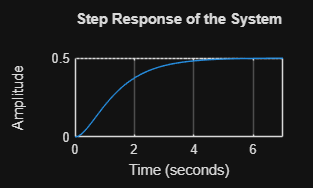



%% PART 4 : TIME DOMAIN ANALYSIS

figure
step(G)
title('Step Response of the System')
grid on

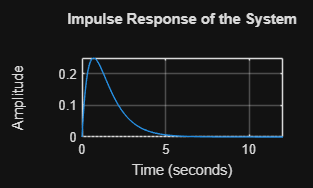


figure
impulse(G)
title('Impulse Response of the System')
grid on

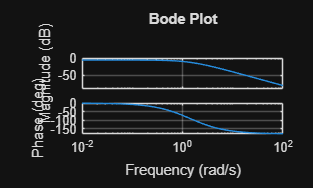



%% PART 5 : FREQUENCY RESPONSE ANALYSIS

figure
bode(G)
title('Bode Plot')
grid on

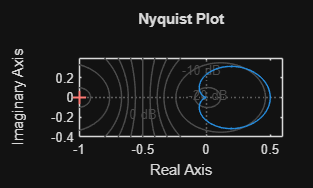


figure
nyquist(G)
title('Nyquist Plot')
grid on



%% PART 6 : CONVERSION TO STATE SPACE

[A,B,C,D] = tf2ss(num,den);

disp('State Space Matrices')

State Space Matrices



disp('Matrix A:')

Matrix A:


disp(A)

    -3    -2
     1     0




disp('Matrix B:')

Matrix B:


disp(B)

     1
     0




disp('Matrix C:')

Matrix C:


disp(C)

     0     1




disp('Matrix D:')

Matrix D:


disp(D)

     0





%% PART 7 : STATE SPACE MODEL

sys_ss = ss(A,B,C,D);

disp('State Space System:')

State Space System:


sys_ss


sys_ss =
 
  A = 
       x1  x2
   x1  -3  -2
   x2   1   0
 
  B = 
       u1
   x1   1
   x2   0
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


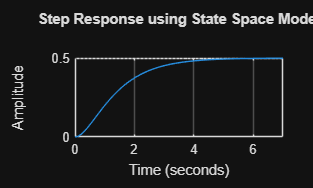



%% PART 8 : STATE SPACE RESPONSE

figure
step(sys_ss)
title('Step Response using State Space Model')
grid on



%% PART 9 : CONVERT BACK TO TRANSFER FUNCTION

[num2,den2] = ss2tf(A,B,C,D);

disp('Transfer Function obtained from State Space:')

Transfer Function obtained from State Space:



G2 = tf(num2,den2)


G2 =
 
        1
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.
